# Figure 3F, S4G

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A010_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 20×5 cell array
    {'siCtrl DMSO'         }    {[1 2 3 4]}    {[2]}    {[1]}    {[0 0 0]}
    {'siCtrl DOX'          }    {[5 6 7 8]}    {[2]}    {[1]}    {[0 0 0]}
    {'siCCNE/siCtrl DMSO'  }    {[1 2 3 4]}    {[3]}    {[1]}    {[0 0 0]}
    {'siCCNE/siCtrl DOX'   }    {[5 6 7 8]}    {[3]}    {[1]}    {[0 0 0]}
    {'siCCNA/siCtrl DMSO'  }    {[1 2 3 4]}    {[4]}    {[1]}    {[0 0 0]}
    {'siCCNA/siCtrl DOX'   }    {[5 6 7 8]}    {[4]}    {[1]}    {[0 0 0]}
    {'siSkp2/siCCNA DMSO'  }    {[1 2 3 4]}    {[5]}    {[1]}    {[0 0 0]}
    {'siSkp2/siCCNA DOX'   }    {[5 6 7 8]}    {[5]}    {[1]}    {[0 0 0]}
    {'siSkp2/siCDC25a DMSO'}    {[1 2 3 4]}    {[6]}    {[1]}    {[0 0 0]}
    {'siSkp2/siCDC25a DOX' }    {[5 6 7 8]}    {[6]}    {[1]}    {[0 0 0]}
    {'siCDC25a/siCCNA DMSO'}    {[1 2 3 4]}    {[7]}    {[1]}    {[0 0 0]}
    {'siCDC25a/siCCNA DOX' }    {[5 6 7 8]}    {[7]}    {[1]}    {[0 0 0]}
    {'siCCNA/siCCNE DMSO'  }    {[1 2 3 4]}    {[8]}    {[1]}    {[0 0 


framesPerHr = 60/12;
frameDrugAdded = 13;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        if dat.POI(n,1) + round(20*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)));
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .7;
        end
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) <numFrames - 1 * framesPerHr
            crlGate(n) = dat.crlNormAct(n,dat.POI(n,1) - 1 * framesPerHr) >  .5 & ...
               dat.crlNormAct(n,dat.POI(n,1) + 1 * framesPerHr) > .5;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;
   S(i).crlGate = crlGate;
        S(i).cdkHighGate = cdkHighGate;

end

S4G left

conds=[1 3];
colors = [.1 .4 1;.5 .8 .2];
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 3];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,POI_align)) &  ...
         data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) & data.apcExpressGate & data.goodCdk;
sum(inds)
    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));
    yvals = yvals(yvals < 2000 & yvals >= 0);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 475

ans = 367

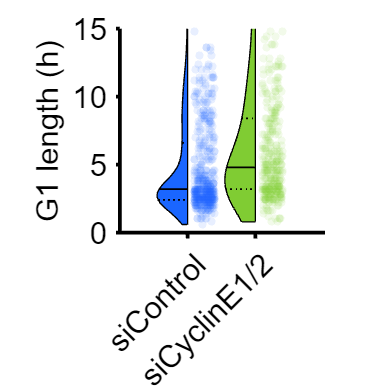


figure('Units', 'Inches', 'Position', [0, 0, 5, 5])
set(gca,'fontsize',12)
h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'G1 length (h)'])

set(gca,'linewidth',2,'fontsize',17)
xticklabels({'siControl','siCyclinE1/2'})
ylim([0 15])
 xtickangle(45)
axis square





p1=mediantest(ally(groups==1),ally(groups==2))

p1 = 2.7001e-10



 % print_pdf(['fig_S4Gleft.pdf'])

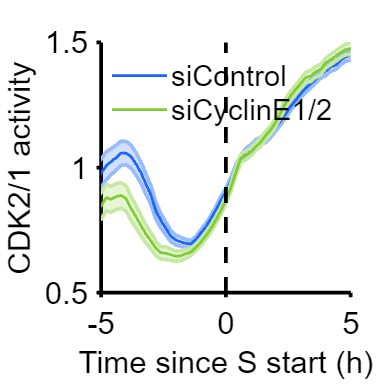

conds=[1 3];
timeGate = [0 3];
colors = [.1 .4 1;.5 .8 .2;.1 .4 1;  .5 .1 .702;.8 .2 .6;.9 .4 0;1 .6 0; 1 .3 .2; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(S(conds(i)).POI(:,POI_align)) &  ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1)&...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;

    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5});
end
set(gca,'linewidth',2,'fontsize',17)
ylabel({'CDK2/1 activity'});xlabel('Time since S start (h)');
legend('siControl','siCyclinE1/2','box','off','Location','north','fontsize',16);

xlim([-5 5]); 
ylim([.5 1.5]);
vline([0],'k--')

% print_pdf(['fig_S4Gright.pdf'])